clc;
clear all;
imageName='san_antonio_no_soleado.tif';
task="7924a668-3a29-4886-b08c-3093d8330265";
lote=3;
imagenRGB=obtenerImageSegmented(imageName);

%imageSegmented=segmentarPorKmeans(3,3,imagenRGB);


% Segmentar mediante Color Thresold
[imageSegmented] =segmentImageUsingColorThreshold(imagenRGB);

Aplicación de gradiente

[fgm4,gmag] =ejecutarWatershedForegroundMarkersProcess(imageSegmented);

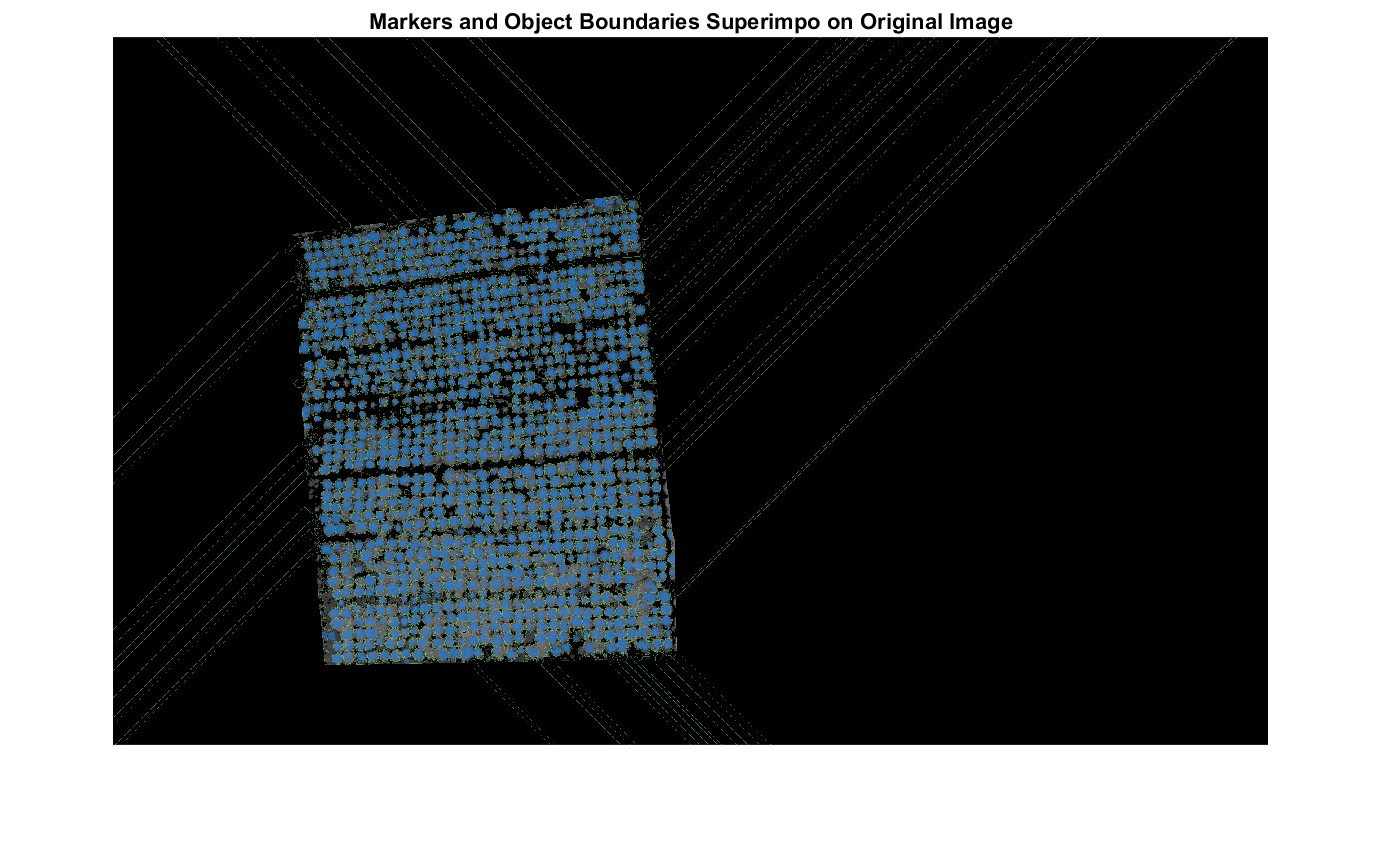


labels=ejecutarWatershedBackgroundMarkers(fgm4,gmag,imageSegmented);


labelsToImage = imdilate(labels==0,ones(3,3)) + 2*bgm + 3*fgm4;

Unrecognized function or variable 'bgm'.

I4 = labeloverlay(imageSegmented(:,:,3),labelsToImage);
imshow(I4)
title('Markers and Object Boundaries Superimpo on Original Image')


procesarLabelsResult(labels,imageSegmented,imageName,lote,task);

ddb454fa-0f63-4b5a-bc88-50637f675232
Se ha creado la tarea con ID: ddb454fa-0f63-4b5a-bc88-50637f675232
Inicia consulta con URL: http://localhost:8000/api/plugins/measure/task/7924a668-3a29-4886-b08c-3093d8330265/volume/check/ddb454fa-0f63-4b5a-bc88-50637f675232
<Response [200]>
{'ready': False}
<Response [200]>
{'ready': False}
<Response [200]>
{'ready': True}
True
Volumen
1.24
*Valores a Insertar*
INSERT INTO plant (contorno,area,volumen,ndvi_avg,centro,posicion_algoritmo,data_statistic,cod_lote,contorno_image_separated) VALUES (%s,%s,%s,%s,%s,%s,%s,%s,%s)
1 record inserted.
dabe2269-70a0-4510-b3eb-64ccf2e669c2
Se ha creado la tarea con ID: dabe2269-70a0-4510-b3eb-64ccf2e669c2
Inicia consulta con URL: http://localhost:8000/api/plugins/measure/task/7924a668-3a29-4886-b08c-3093d8330265/volume/check/dabe2269-70a0-4510-b3eb-64ccf2e669c2
<Response [200]>
{'ready': False}
<Response [200]>
{'ready': False}
<Response [200]>
{'ready': True}
True
Volumen
0.22
*Valores a Insertar*
INSERT INTO p